# dAdt to dNdt model - New UseNests

Present model that correlates pop growth rate (dNdt) to digging rate (dAdt) and integrates it to get tArea. trying different t1 intervals and weights for dNdt influence on dAdt.

## Correlation Matrix for t1 interval influence on dAdt (uniform weights)

Calc the correlation coefficient for between dNdt and dAdt where dNdt is calculated based on the sum of dNdt for each day between lag $t_a$ and lag $t_b$. Results are presented in heatmap, where x axis represent $t_a$ and y, $t_b$.

load('Data\MeanData\MeanBinnedData.mat','S','M','t','varNames')
UseNests = [3:6,8,11:13,15:18,20,22,25:29];
t0 = find(t==0); tend = find(t==135);
t1 = t(t0:tend);

A = mean(M(11).BinMat(t0:tend,UseNests),2);
Asd = std(M(11).BinMat(t0:tend,UseNests),0,2);
Aer = Asd./sqrt(length(UseNests)); % error as SEM

N = mean(M(13).BinMat(t0:tend,UseNests),2);
Nsd = std(M(13).BinMat(t0:tend,UseNests),0,2);
Ner = Nsd./sqrt(length(UseNests)); % error as SEM

% rates
dAdt = diff(A)./3;
dNdt = diff(N)./3;

tvec = (-60:3:60)';
tvec0 = (numel(tvec)-1)./2 + 1;
CorrMat = nan(numel(tvec));
PvalMat = nan(numel(tvec));

for i=1:numel(tvec)
    for j=1:numel(tvec)
        if i<j
            continue
        end
        
        SdNdt = zeros(numel(dNdt),1);
        for k=1:numel(dNdt)-1
            if k-(tvec0-j)<1
                ta = 1;
            else
                ta = k-(tvec0-j);
            end
            if k+(i-tvec0)>=numel(dNdt)
                tb = numel(dNdt);
            else
                tb = k+(i-tvec0);
            end
            SdNdt(k) = sum(dNdt(ta:tb));

            if SdNdt(k)<0
                SdNdt(k)=0;
            end
            SdNdt(k) = SdNdt(k)./3;
        end
        [r,Pval] = corrcoef(SdNdt,dAdt,'rows','complete');
        CorrMat(i,j) = r(1,2);
        PvalMat(i,j) = Pval(1,2);
        
    end
end

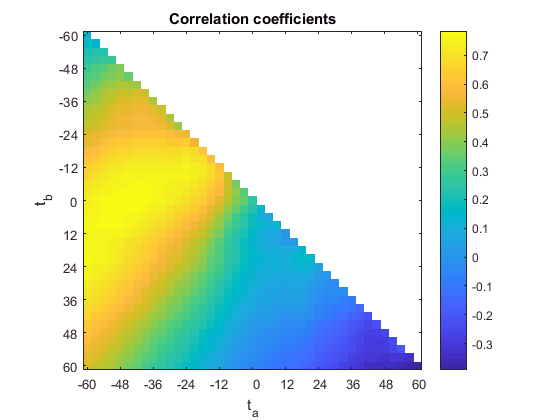


%% plot all
figure;
tvecNew = [-60:12:60]';
L = tril(ones(numel(tvec)));
f = imagesc(CorrMat);
f.AlphaData = L;
xticks(1:4:41)
xticklabels(cellstr(num2str(tvecNew)))
yticks(1:4:41)
yticklabels(cellstr(num2str(tvecNew)))
xlabel('t_a')
ylabel('t_b')
axis square
title('Correlation coefficients')
colorbar

The correlation between dNdt and dAdt of a specific day is low (not extremely) at r=0.28.

## Take interval with the max correlation and use it to model the relationship btwn dNdt and dAdt

MaxR = max(max(CorrMat,[],'omitnan'))

MaxR = 0.7838

[MaxR_tb,MaxR_ta]=find(CorrMat==MaxR)

MaxR_tb = 21

MaxR_ta = 5

disp(['Interval from day ',num2str(tvec(MaxR_ta)),' to day ',num2str(tvec(MaxR_tb))])

Interval from day -48 to day 0


## Make Linear model of y=mx+b, to predict dig reate from SdP

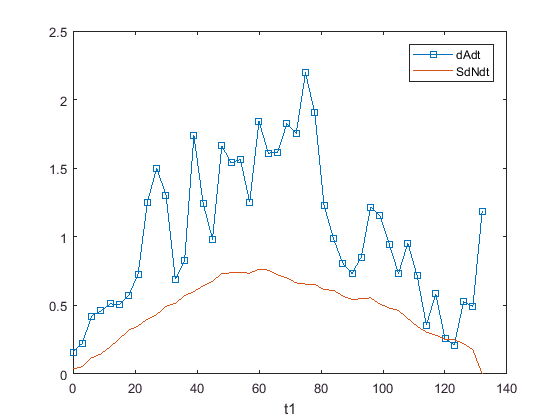

SdNdt = zeros(numel(dNdt),1);
i = MaxR_tb; j = MaxR_ta;
for k=1:numel(dNdt)-1
    if k-(tvec0-j)<1
        ta = 1;
    else
        ta = k-(tvec0-j);
    end
    if k+(i-tvec0)>=numel(dNdt)
        tb = numel(dNdt);
    else
        tb = k+(i-tvec0);
    end
    SdNdt(k) = sum(dNdt(ta:tb));
    if SdNdt(k)<0
        SdNdt(k)=0;
    end
    SdNdt(k) = SdNdt(k)./3;
end
figure
plot(t1(1:end-1),dAdt,'-s',t1(1:end-1),SdNdt)
xlabel('t1')
legend({'dAdt','SdNdt'})

find linear fit

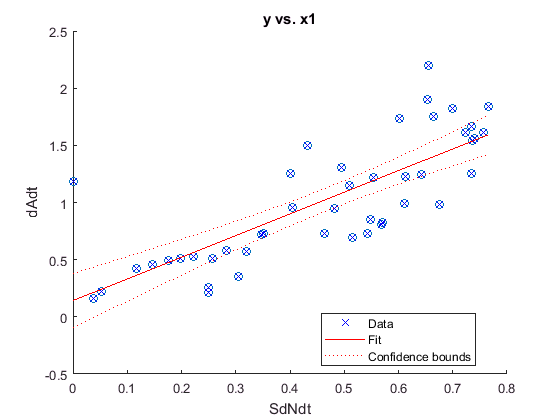

figure
lm = fitlm(SdNdt,dAdt);
figure
scatter(SdNdt,dAdt)
hold on
plot(lm)
xlabel('SdNdt')
ylabel('dAdt')

lm

lm = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________
    (Intercept)    0.14207     0.11708    1.2134       0.23161
    x1              1.8951     0.22897    8.2768    1.9287e-10

Number of observations: 45, Error degrees of freedom: 43
Root Mean Squared Error: 0.335
R-squared: 0.614,  Adjusted R-Squared 0.605
F-statistic vs. constant model: 68.5, p-value = 1.93e-10

Use linear fit to model dAdt from SdNdt. 

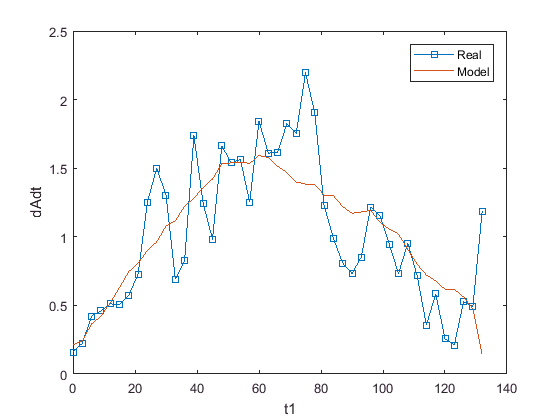

%LM = @(dp) lm.Coefficients{1,1}+lm.Coefficients{2,1}.*dp;
MdAdt = predict(lm,SdNdt);
figure
plot(t1(1:end-1),dAdt,'-s',t1(1:end-1),MdAdt)
xlabel('t1')
ylabel('dAdt')
legend({'Real','Model'})

RMSE = sqrt(immse(dAdt,MdAdt))

RMSE = 0.3278

ExpVariance = 1-(var(dAdt-MdAdt)/var(dAdt))

ExpVariance = 0.6144

Now integrate modeled dAdt to get modeled A

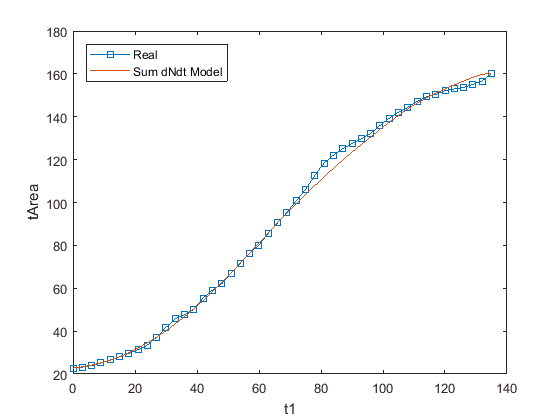

A_m = zeros(length(A),1);
A_m(1) = A(1);
for i=2:numel(A_m)
    A_m(i) = A_m(i-1)+3*MdAdt(i-1); %* remember to multiply by 3 for t1 step
end

figure
plot(t1,A,'-s',t1,A_m)
xlabel('t1')
ylabel('tArea')
legend({'Real','Sum dNdt Model'},'Location', 'NorthWest')

RMSE_integrated = sqrt(immse(A,A_m))

RMSE_integrated = 2.1920

# make model of dAdt = m*SdNdt (scale factor)

setup model

SdNdt = zeros(numel(dNdt),1);
for k=1:numel(dNdt)-1
    if k-(tvec0-4)<1 % day -51 is indexed as 4
        ta = 1;
    else
        ta = k-(tvec0-4);
    end
    tb = k;
    SdNdt(k) = sum(dNdt(ta:tb));    
    if SdNdt(k)<0
        SdNdt(k)=0;
    end
    SdNdt(k) = SdNdt(k)./3;
end

lm0 = fitlm(SdNdt,dAdt,'y~x1-1') % linear model with y intercept at 0

lm0 = Linear regression model:
    y ~ x1

Estimated Coefficients:
          Estimate       SE       tStat      pValue  
          ________    ________    _____    __________
    x1    2.0392      0.094626    21.55    5.2034e-25

Number of observations: 45, Error degrees of freedom: 44
Root Mean Squared Error: 0.341

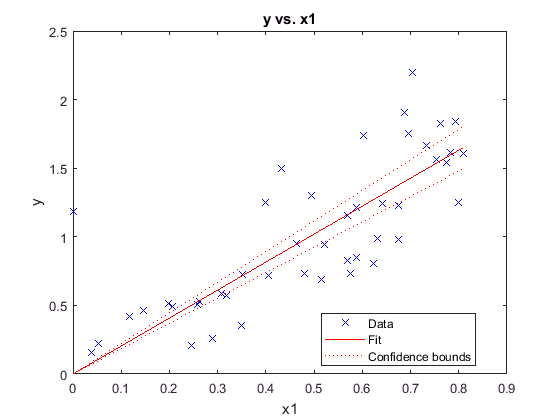

plot(lm0)

Now integrate modeled dAdt with min RMSE "m" value

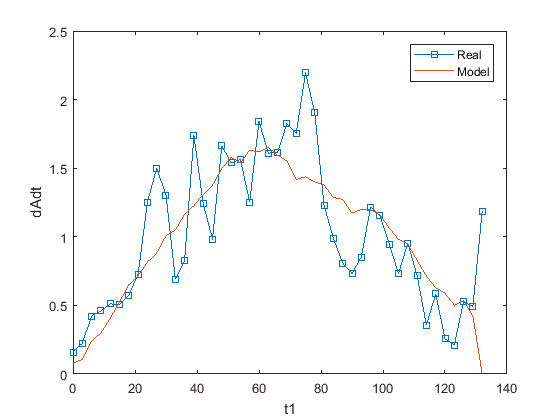

MdAdt = predict(lm0,SdNdt);
figure
plot(t1(1:end-1),dAdt,'-s',t1(1:end-1),MdAdt)
xlabel('t1')
ylabel('dAdt')
legend({'Real','Model'})

RMSE = sqrt(immse(dAdt,MdAdt))

RMSE = 0.3375

ExpVariance = 1-(var(dAdt-MdAdt)/var(dAdt))

ExpVariance = 0.5937

r = corrcoef(dAdt,MdAdt);
r = r(1,2)

r = 0.7777

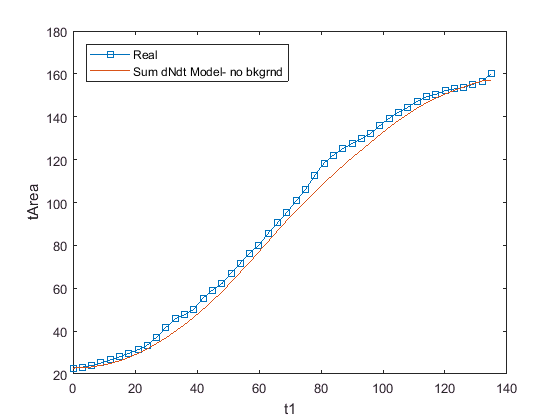


% integrate
A_m = zeros(length(A),1);
A_m(1) = A(1);
for i=2:numel(A_m)
    A_m(i) = A_m(i-1)+3*MdAdt(i-1); %* remember to multiply by 3 for t1 step
end

figure
plot(t1,A,'-s',t1,A_m)
xlabel('t1')
ylabel('tArea')
legend({'Real','Sum dNdt Model- no bkgrnd'},'Location', 'NorthWest')

RMSE_integrated = sqrt(immse(A,A_m))

RMSE_integrated = 2.8111

MeanAbsE = mean(abs(A-A_m))

MeanAbsE = 2.2778

MSE = (RMSE_integrated)^2

MSE = 7.9025

absE = abs(A-A_m);
SDabsE = std(absE);
PercentGoodAE = sum(absE<=MeanAbsE+SDabsE)/numel(absE)

PercentGoodAE = 0.8723

PercentAccurate= sum(absE<=4)/numel(absE)

PercentAccurate = 0.8723

## Test alternatives models: model that sums dNdt from day 1 (similar to pop(t) but no the same)

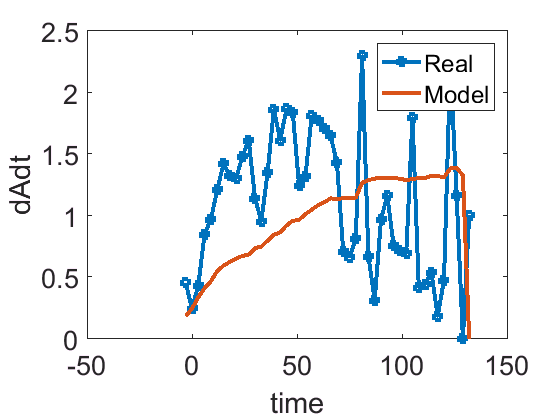

SdNdt = zeros(numel(dNdt),1);
for k=1:numel(dNdt)-1
    ta = 1;
    tb = k;
    SdNdt(k) = sum(dNdt(ta:tb));
    if SdNdt(k)<0
        SdNdt(k)=0;
    end
    SdNdt(k) = SdNdt(k)./3;
end
% find linear fit
lm1 = fitlm(SdNdt,dAdt,'y~x1-1');
MdAdt = predict(lm1,SdNdt);
figure
plot(t1(1:end-1),dAdt,'-s',t1(1:end-1),MdAdt,'LineWidth',3)
xlabel('t1')
ylabel('dAdt')
legend({'Real','Model'})

% eval
RMSE = sqrt(immse(dAdt,MdAdt))

RMSE = 0.6882

ExpVariance = 1-(var(dAdt-MdAdt)/var(dAdt))

ExpVariance = -0.4211

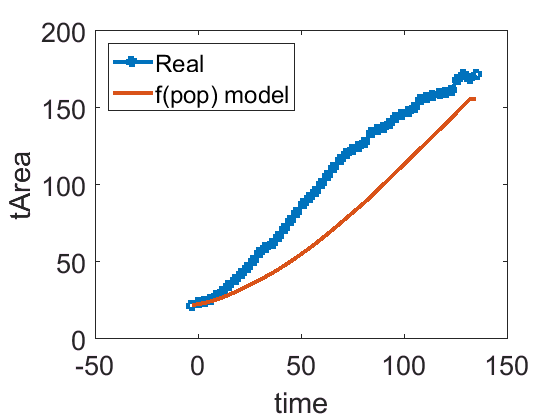

% integrate
A_m = zeros(length(A),1);
A_m(1) = A(1);
for i=2:numel(A_m)
    A_m(i) = A_m(i-1)+3*MdAdt(i-1); %* remember to multiply by 3 for t1 step
end

figure
plot(t1,A,'-s',t1,A_m,'LineWidth',3)
xlabel('t1')
ylabel('tArea')
%legend({'Real','Sum from 1 dNdt Model'},'Location', 'NorthWest')
legend({'Real','f(pop) model'},'Location', 'NorthWest')

RMSE_integrated = sqrt(immse(A,A_m))

RMSE_integrated = 27.4368

**VERY similar result to dAdt corr. to pop model.**

# problem of Linear model of y=mx+b

the problem is that given 0 pop growth rate, dig rate is not 0. meaning there is somekind of constant digging in t1. while this may be true for the mean data, it is most likely not true for the specific experiments. So try out the 2 different models on the nests

**Conclusion both linear model and the scale factor model reach very low RMSE values (<4). linear model reached slighly better RMSE vs. the mean data.**

**The real test is on the specific experiments in 'EvalModelNests-newUseNests.mlx'**